# Bodies

A body is an object of class `body`, which is a subclass of `frame`. Essentially, `body` adds a mass and a tensor of inertia I0 to `point`, and methods to compute useful quantities such as the linear and angular momentum or the kinetic energy. Additionally, a triangulation can be stored in the object with the body's geometry. This tutorial focuses on the specific aspects of `body`.

Start by importing the Anakin framework into Matlab. Be sure to include Anakin's base directory before you run this line:

import anakin.*

## Object creation

The default body has mass 1 and no intrinsic tensor of inertia, and is located at the canonical origin:

b = body % default call

b = Rigid body with mass:
     1

Inertia tensor at the center of mass in body basis:
     0     0     0
     0     0     0
     0     0     0

Coordinates of the center of mass:
     0
     0
     0

And basis with rotation matrix:
     1     0     0
     0     1     0
     0     0     1


A body can be created by passing properties to the constructor. **Important:** remember that the intrinsic tensor of inertia I0 about the center of mass of the body must be supplied as a tensor in the canonical vector basis.

m = 20;
rA = point([1;2;3])

rA = Point with coordinates:
     1
     2
     3


phi = pi/6;
Bb = basis([1;0;0],[0;cos(phi);sin(phi)],[0;-sin(phi);cos(phi)]);
I0 = tensor(diag([1,2,3]),Bb); % We write Bb to give the tensor components in Bb
b = body(m,rA,Bb,I0) % as a vector

b = Rigid body with mass:
    20

Inertia tensor at the center of mass in body basis:
    1.0000         0         0
         0    2.0000   -0.0000
         0    0.0000    3.0000

Coordinates of the center of mass:
     1
     2
     3

And basis with rotation matrix:
    1.0000         0         0
         0    0.8660   -0.5000
         0    0.5000    0.8660


## Tensor of inertia

The tensor of inertia of the body can be easily computed about any point, and expressed in any vector basis (it is an object of class tensor):

O = point(); % origin
A = point([1;2;3]); % origin

I = b.I(O) % tensor with respect to the origin

I = Second-order tensor with components:
  261.0000  -40.0000  -60.0000
  -40.0000  202.2500 -120.4330
  -60.0000 -120.4330  102.7500


I = b.I(A) % tensor about the center of mass, but expressed in the canonical vector basis

I = Second-order tensor with components:
    1.0000         0         0
         0    2.2500   -0.4330
         0   -0.4330    2.7500


I.components(Bb) % expressed in the body basis

ans =     1.0000         0         0
         0    2.0000   -0.0000
         0    0.0000    3.0000


## Dynamics

The linear, angular momentum and the kinetic energy of the body in a given reference frame can be easily computed as follows. We introduce symbolic variables to enable differentiation:

syms t xi(t) eta(t) zeta(t) psi(t) theta(t) phi(t); % declare symbolic variables
assume([in(t, 'real'), in(xi(t), 'real'), in(eta(t), 'real'), in(zeta(t), 'real'), in(psi(t), 'real'), in(theta(t), 'real'), in(phi(t), 'real')]); 

B0 = basis;
B1 = B0.rotatez(psi);
B2 = B1.rotatex(theta);
Bb = B2.rotatez(phi);
I0 = tensor(diag([1,2,3]),Bb); 
b = body(5,[xi,eta,zeta],Bb,I0) % a symbolic body

b = Rigid body with mass:
     5

Inertia tensor at the center of mass in body basis:
     1     0     0
     0     2     0
     0     0     3

Coordinates of the center of mass:
   xi(t)
  eta(t)
 zeta(t)
 
And basis with rotation matrix:
[ cos(phi(t))*cos(psi(t)) - cos(theta(t))*sin(phi(t))*sin(psi(t)), - cos(psi(t))*sin(phi(t)) - cos(phi(t))*cos(theta(t))*sin(psi(t)),  sin(psi(t))*sin(theta(t))]
[ cos(phi(t))*sin(psi(t)) + cos(psi(t))*cos(theta(t))*sin(phi(t)),   cos(phi(t))*cos(psi(t))*cos(theta(t)) - sin(phi(t))*sin(psi(t)), -cos(psi(t))*sin(theta(t))]
[                                       sin(phi(t))*sin(theta(t)),                                         cos(phi(t))*sin(theta(t)),              cos(theta(t))]
 


% a moving and rotating frame
S1 = frame([xi,0,0],B1)

S1 = Frame with origin with coordinates:
 xi(t)
     0
     0
 
And basis with rotation matrix:
[ cos(psi(t)), -sin(psi(t)), 0]
[ sin(psi(t)),  cos(psi(t)), 0]
[           0,            0, 1]
 


% linear momentum
b.p % use default reference frame: canonical frame

ans = Vector with components:
   5*diff(xi(t), t)
  5*diff(eta(t), t)
 5*diff(zeta(t), t)
 

b.p(S1)

ans = Vector with components:
 5*eta(t)*diff(psi(t), t)
        5*diff(eta(t), t)
       5*diff(zeta(t), t)
 


% angular momentum
b.H(O) % the point about which the angular momentum is computed

ans = Vector with components:
 5*eta(t)*diff(zeta(t), t) - (cos(psi(t))*diff(theta(t), t) + sin(psi(t))*sin(theta(t))*diff(phi(t), t))*(cos(psi(t))^2 + 2*cos(theta(t))^2 + cos(phi(t))^2*cos(psi(t))^2 - cos(phi(t))^2*cos(theta(t))^2 - 2*cos(psi(t))^2*cos(theta(t))^2 + cos(phi(t))^2*cos(psi(t))^2*cos(theta(t))^2 - 2*cos(phi(t))*cos(psi(t))*cos(theta(t))*sin(phi(t))*sin(psi(t)) - 3) - (sin(psi(t))*diff(theta(t), t) - cos(psi(t))*sin(theta(t))*diff(phi(t), t))*(cos(psi(t))*sin(psi(t)) - cos(phi(t))*cos(theta(t))*sin(phi(t)) + cos(phi(t))^2*cos(psi(t))*sin(psi(t)) - 2*cos(psi(t))*cos(theta(t))^2*sin(psi(t)) + cos(phi(t))^2*cos(psi(t))*cos(theta(t))^2*sin(psi(t)) + 2*cos(phi(t))*cos(psi(t))^2*cos(theta(t))*sin(phi(t))) - 5*zeta(t)*diff(eta(t), t) - sin(theta(t))*(cos(theta(t))*diff(phi(t), t) + diff(psi(t), t))*(cos(phi(t))*cos(psi(t))*sin(phi(t)) - 2*cos(theta(t))*sin(psi(t)) + cos(phi(t))^2*cos(theta(t))*sin(psi(t)))
                                       5*zeta(t)*diff(xi(t), t) - 5*xi(t)

b.H(O,S1) 

ans = Vector with components:
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                     2*cos(psi(t))*diff(theta(t), t) + 5*eta(t)*diff(zeta(t), t) - 5*zeta(t)*diff(eta(t), t) - cos(phi(t))^2*cos(psi(t))*diff(theta(t), t) + 3*sin(psi(t))*sin(theta(t))*diff(phi(t), t) + cos(phi(t))*cos(theta(t))*sin(phi(t))*sin(psi(t))*diff(theta(t), t)
 (sin(psi(t))*diff(theta(t), t) - cos(psi(t))*sin(theta(t))*diff(phi(t), t))*(cos(psi(t))^2 - cos(phi(t))^2 + cos(phi(t))^2


% kinetic energy
b.T

ans = Scalar with value:
(3*diff(phi(t), t)^2)/2 + diff(psi(t), t)^2/2 + diff(theta(t), t)^2 + (cos(phi(t))^2*diff(psi(t), t)^2)/2 - (cos(phi(t))^2*diff(theta(t), t)^2)/2 + cos(theta(t))^2*diff(psi(t), t)^2 + (5*abs(diff(eta(t), t))^2)/2 + (5*abs(diff(xi(t), t))^2)/2 + (5*abs(diff(zeta(t), t))^2)/2 + 3*cos(theta(t))*diff(phi(t), t)*diff(psi(t), t) - (cos(phi(t))^2*cos(theta(t))^2*diff(psi(t), t)^2)/2 - cos(phi(t))*sin(phi(t))*sin(theta(t))*diff(psi(t), t)*diff(theta(t), t)
 

b.T(S1) 

ans = Scalar with value:
(3*diff(phi(t), t)^2)/2 + diff(theta(t), t)^2/2 + (sin(phi(t))^2*diff(theta(t), t)^2)/2 + (5*abs(diff(eta(t), t))^2)/2 + (5*abs(diff(zeta(t), t))^2)/2 + (5*abs(eta(t)*diff(psi(t), t))^2)/2
 

## Plotting

The `body` class supports a triangulation of the object, which can be used for plotting. The default body shows as a cube. There are some convenience functions to create boxes, cylinders, cones, and spheres:

% Particularize the body for specific values of t, xi, eta... before plotting
b0 = b.subs({t,xi,eta,zeta,psi,theta,phi},{0,1,2,3,pi/4,pi/6,pi/7})

b0 = Rigid body with mass:
     5

Inertia tensor at the center of mass in body basis:
    1.0000   -0.0000   -0.0000
    0.0000    2.0000    0.0000
   -0.0000         0    3.0000

Coordinates of the center of mass:
     1
     2
     3

And basis with rotation matrix:
    0.3714   -0.8585    0.3536
    0.9028    0.2449   -0.3536
    0.2169    0.4505    0.8660



S0 = frame()

S0 = Frame with origin with coordinates:
     0
     0
     0

And basis with rotation matrix:
     1     0     0
     0     1     0
     0     0     1


S0.plot; % plot the canonical reference frame

b0.plot('linestyle','none') % plot the body

ans =     0.0001    1.0001    2.0001    3.0001    4.0001    5.0001    6.0001    7.0001    8.0001    9.0001   10.0001   11.0001


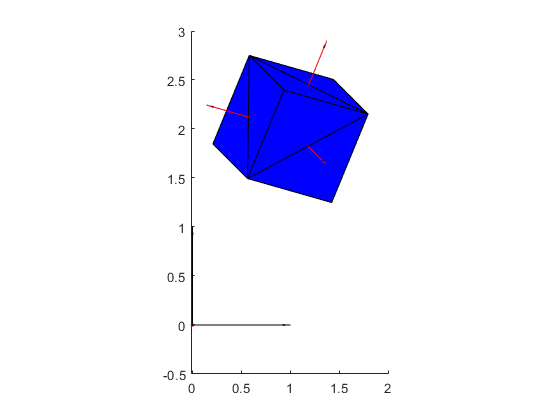

frame(b0).plot('color', 'r','facecolor','r'); % plot the reference frame of the body

light; % add light